# Setting Assumptions

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code defines and plots the expression `expr`.

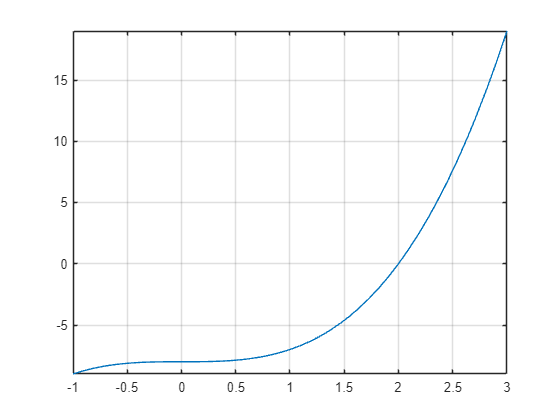

syms x
y = x^3 - 8;
fplot(y, [-1 3])
grid on

## Task 1

In the script, the expression *x^*3−8 is plotted. To find where the line crosses the x-axis, you can create an equation which sets the expression equal to 0, and then solve.

eqn = y == 0;
sol = solve(eqn, x)

$$sol = \left(\begin{array}{c} 2\\ -1-\sqrt{3}\,\mathrm{i}\\ -1+\sqrt{3}\,\mathrm{i} \end{array}\right)$$

## Task 2

In the plot, you can see the line only crosses the x-axis at one location, but `sol` contains three solutions: one real solution and two complex solutions.

The `assume` function lets you place assumptions on symbolic variables so they only take on values from a particular set, like the real numbers.

For example, you can assume the variable `a` is an integer.

`assume``(``a``,``"integer"``)`

assume(x, "real")

## Task 3

Assumptions aren't displayed, so to see all the existing assumptions on a variable, use the `assumptions` function.

`zAsmp` `=` `assumptions``(``z``)`

check = assumptions(x)

$$check = x\in \mathbb{R}$$

## Task 4

Assumptions are used by the function `solve` to restrict the returned solutions. Now that `x` can only be a real number, that information will be used when solving for `x`.

realsol = solve(eqn, x)

$$realsol = 2$$

## Task 5

You should clear the assumptions on a variable when you no longer need them.

`assume``(``var``, "clear"``)`

Because assumptions aren't displayed unless you use the `assumptions` function, uncleared assumptions could inadvertently impact future computations.

assume(x, "clear")